
%load short_modem_rx.mat 
load long_modem_rx.mat
% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission

c = cos(2*pi*f_c/Fs*[0:39660-1]')

c =     1.0000
    0.7200
    0.0368
   -0.6670
   -0.9973
   -0.7691
   -0.1102
    0.6104
    0.9892
    0.8140


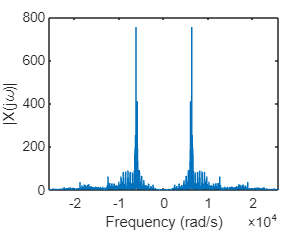

ans = 1.0e+02 *

  -0.0007 - 0.0016i
   0.0009 - 0.0047i
   0.0040 + 0.0016i
  -0.0054 + 0.0010i
  -0.0032 - 0.0023i
   0.0037 + 0.0009i
  -0.0023 + 0.0021i
  -0.0022 - 0.0005i
   0.0047 - 0.0011i
  -0.0022 + 0.0047i


%plot(t, cos_c)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
%%

%soundsc(y_t, Fs)
plot_ft_rad(y_t, Fs)

new_y = y_t.*c;

Arrays have incompatible sizes for this operation.

Related documentation

%soundsc(new_y, Fs)

plot_ft_rad(new_y, Fs)
cutoff = 2*pi*f_c %Set the cutoff frequency for the low-pass filter


%Setup Low Pass Filter%

	W = cutoff;	% set the cutoff frequency to 2 pi * 1000 rads/s
	t = [-100:1:99]*(1/Fs);   % create a 200 sample time vector to generate sinc
	h = W/pi*sinc(W/pi*t);   % this is the impulse response
	plot(t, h);   	% plot h to visualize

	figure
	plot_ft_rad(h, Fs)  % Visualize |H(j\omega)|
	title('Magnitude of H(j\omega)');

	y = conv(new_y, h);     % convolve x with h to filter the noise
	figure
	plot_ft_rad(y, Fs); % plot the magnitude of the FT of the filtered noise
	title('Magnitude of FT of filtered noise');
	soundsc(y, Fs);	% listen to the filtered noise
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


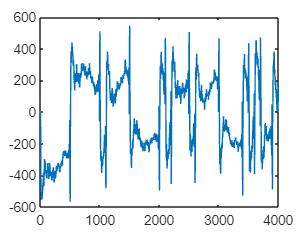


% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits
y = y(150:4149);
y_sqaure = y;
y_sqaure(y_sqaure > 1) = 1;
y_sqaure(y_sqaure < 1) = 0;
clf
plot(y)

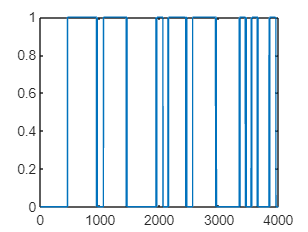

plot(y_sqaure)


y_sqaure = downsample(y_sqaure, 100)

y_sqaure =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


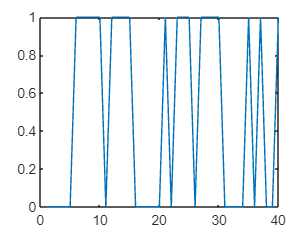

plot(y_sqaure)

BitsToString(y_sqaure)

ans = 'Hello'